# MATLAB Fundamentals

High-level language for technical computing 

- Integrates computation, visualization, and programming 

- Sophisticated data structures, editing and debugging tools, object-oriented programming 

MATrix LABoratory (**MATLAB**)  

- Highly optimized for matrix operations 

- Originally written to provide easy access to matrix software: LINPACK (linear system package) and EISPACK (eigen system package) 

- Basic element is array that does not require dimensioning 

Highly interactive, interpreted programming language 

- Development time usually significantly reduced compared to compiled languages 

**Some key features different from other programming languages:**

- one-based indexing (vs. zero-based indexing)

- Fortran ordering of matrices: columns-wise (vs. row-wise for C/C++) -- access data column-wise

# Data types and structures

## Numerical Arrays

All MATLAB variables are *arrays*: 

scalar

x = 1

x = 1

column vector

x = [1;2]

x =      1
     2


row vector

x = [1 2]

x =      1     2


% or x = [1,2]

matrix

x = [1,2;3,4]

x =      1     2
     3     4


### Array Creation 

#### evenly-spaced vectors

`: `operator (default spacing of 1)

x = 1:10  % or x = 1:1:10

x =      1     2     3     4     5     6     7     8     9    10


x = 1:2:10

x =      1     3     5     7     9


`linspace(``first``,``last``,``number_of_elements``)` 

x =  linspace(1,10,5)

x =     1.0000    3.2500    5.5000    7.7500   10.0000


#### other

`blkdiag, diag, eye, zeros, ones, rand, magic, logspace, true/false...`

`EX.`

eye(3)

ans =      1     0     0
     0     1     0
     0     0     1


ones(3)

ans =      1     1     1
     1     1     1
     1     1     1


diag(ones(3))

ans =      1
     1
     1


diag(diag(ones(3)))

ans =      1     0     0
     0     1     0
     0     0     1


#### grid creation

x = linspace(1,10,6);
y = linspace(0,1,5);
[X,Y] = meshgrid(x,y)

X =     1.0000    2.8000    4.6000    6.4000    8.2000   10.0000
    1.0000    2.8000    4.6000    6.4000    8.2000   10.0000
    1.0000    2.8000    4.6000    6.4000    8.2000   10.0000
    1.0000    2.8000    4.6000    6.4000    8.2000   10.0000
    1.0000    2.8000    4.6000    6.4000    8.2000   10.0000


Y =          0         0         0         0         0         0
    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500
    0.5000    0.5000    0.5000    0.5000    0.5000    0.5000
    0.7500    0.7500    0.7500    0.7500    0.7500    0.7500
    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000


### Array Concatenation

vertically

vertcat(x,x)

ans =     1.0000    2.8000    4.6000    6.4000    8.2000   10.0000
    1.0000    2.8000    4.6000    6.4000    8.2000   10.0000


% or [x;x]

horizontally

horzcat(x,x)

ans =     1.0000    2.8000    4.6000    6.4000    8.2000   10.0000    1.0000    2.8000    4.6000    6.4000    8.2000   10.0000


% or [x,x]

### Indexing and Slicing

M = reshape(linspace(11,18,8),[2,2,2])

M = M(:,:,1) =

    11    13
    12    14


M(:,:,2) =

    15    17
    16    18


Linear indexing and colon operator

M(1)

ans = 11

M(5:8)

ans =     15    16    17    18


M(:,1,1)

ans =     11
    12


Indexing with arrays 

M([1,3,5,8])

ans =     11    13    15    18


A = [1,5,2;8,3,2;7,4,6];
M(A)

ans =     11    15    12
    18    13    12
    17    14    16


Component-wise indexing with arrays

M([1,2],[2,1],[1,2])

ans = ans(:,:,1) =

    13    11
    14    12


ans(:,:,2) =

    17    15
    18    16


A = [2,1;2,1]

A =      2     1
     2     1


M(A,[2,1],1)

ans =     14    12
    14    12
    13    11
    13    11


% equals component-wise indexing with vectorized arrays
B = reshape(A,1,[]) % convert to row vector

B =      2     2     1     1


M(B,[2,1],1)

ans =     14    12
    14    12
    13    11
    13    11


B = reshape(A,[],1) % convert to column vector

B =      2
     2
     1
     1


M(B,[2,1],1)

ans =     14    12
    14    12
    13    11
    13    11


Logical indexing 

A = mod(M,2)==0

A = 2×2×2 logical array
A(:,:,1) =

   0   0
   1   1


A(:,:,2) =

   0   0
   1   1


M(A)

ans =     12
    14
    16
    18


% random matrix
R = rand(4)

R =     0.2856    0.6107    0.8873    0.4217
    0.7968    0.7038    0.0558    0.4113
    0.1428    0.3833    0.1382    0.9591
    0.5046    0.7287    0.8631    0.7502


R(R>0.8)

ans =     0.8873
    0.8631
    0.9591


find(R>0.8)

ans =      9
    12
    15


R(find(R>0.8))

ans =     0.8873
    0.8631
    0.9591


`end` keyword

M(end-2:end)

ans =     16    17    18


### Reshaping and Sorting

`reshape`

R = rand(4)

R =     0.9810    0.5003    0.4009    0.9643
    0.2335    0.5703    0.9950    0.6712
    0.0962    0.9766    0.2610    0.2992
    0.3846    0.4929    0.6653    0.5311


numel(R)

ans = 16

reshape(R,[],2)

ans =     0.9810    0.4009
    0.2335    0.9950
    0.0962    0.2610
    0.3846    0.6653
    0.5003    0.9643
    0.5703    0.6712
    0.9766    0.2992
    0.4929    0.5311


reshape(R,2,[])

ans =     0.9810    0.0962    0.5003    0.9766    0.4009    0.2610    0.9643    0.2992
    0.2335    0.3846    0.5703    0.4929    0.9950    0.6653    0.6712    0.5311


`repmat`

% tiles R along N dimensional specified number of times
repmat(R,[2,3])

ans =     0.9810    0.5003    0.4009    0.9643    0.9810    0.5003    0.4009    0.9643    0.9810    0.5003    0.4009    0.9643
    0.2335    0.5703    0.9950    0.6712    0.2335    0.5703    0.9950    0.6712    0.2335    0.5703    0.9950    0.6712
    0.0962    0.9766    0.2610    0.2992    0.0962    0.9766    0.2610    0.2992    0.0962    0.9766    0.2610    0.2992
    0.3846    0.4929    0.6653    0.5311    0.3846    0.4929    0.6653    0.5311    0.3846    0.4929    0.6653    0.5311
    0.9810    0.5003    0.4009    0.9643    0.9810    0.5003    0.4009    0.9643    0.9810    0.5003    0.4009    0.9643
    0.2335    0.5703    0.9950    0.6712    0.2335    0.5703    0.9950    0.6712    0.2335    0.5703    0.9950    0.6712
    0.0962    0.9766    0.2610    0.2992    0.0962    0.9766    0.2610    0.2992    0.0962    0.9766    0.2610    0.2992
    0.3846    0.4929    0.6653    0.5311    0.3846    0.4929    0.6653    0.5311    0.3846    0.4929    0.6653    0.5311


`fliplr, flipud`

A = [1,2,3;4,5,6]

A =      1     2     3
     4     5     6


% flip matrix in left/right direction
fliplr(A)

ans =      3     2     1
     6     5     4


% flip matrix in up/down direction
flipud(A)

ans =      4     5     6
     1     2     3


`squeeze`

% remove singleton dimensions
A = ones(2,1,2)

A = A(:,:,1) =

     1
     1


A(:,:,2) =

     1
     1


squeeze(A)

ans =      1     1
     1     1


`sort`

A = [2,4,3;1,6,2]

A =      2     4     3
     1     6     2


% sorted elements of A along dimension specified
sort(A,1) % default order: ascending 

ans =      1     4     2
     2     6     3


sort(A,2,'descend')

ans =      4     3     2
     6     2     1


`sortrows (`based on the elements in the first column)

sort(A,1,'ascend')

ans =      1     4     2
     2     6     3


sortrows(A)

ans =      1     6     2
     2     4     3


#### **Quiz.** 

For the same matrix `M = reshape(linspace(11,18,8),[2,2,2])`, use two different ways to index into the all the odd entries of the matrix.

M = reshape(linspace(11,18,8),[2,2,2]);


clear; clc

## Cell and Cell Arrays

- Collection of data of *any* MATLAB type 

- Additional flexibility over numeric array: Price of generality is storage efficiency.

- Constructed with `{}` or `cell`

- Cell arrays are MATLAB arrays of cell

- Cell **containers** indexed using `(): c(i)` returns ith cell of cell array `c` 

- Cell **contents** indexed using `{}:` `c{i}` returns contents of ith cell of cell array `c`

`EX.`

c = {14, [1,2;5,10], 'hello world!'};
c

c = 1×3 cell array
    {[14]}    {2×2 double}    {'hello world!'}


class(c(2))

ans = 'cell'

class(c{2})

ans = 'double'

`cellplot` graphically display the structure of an cell array

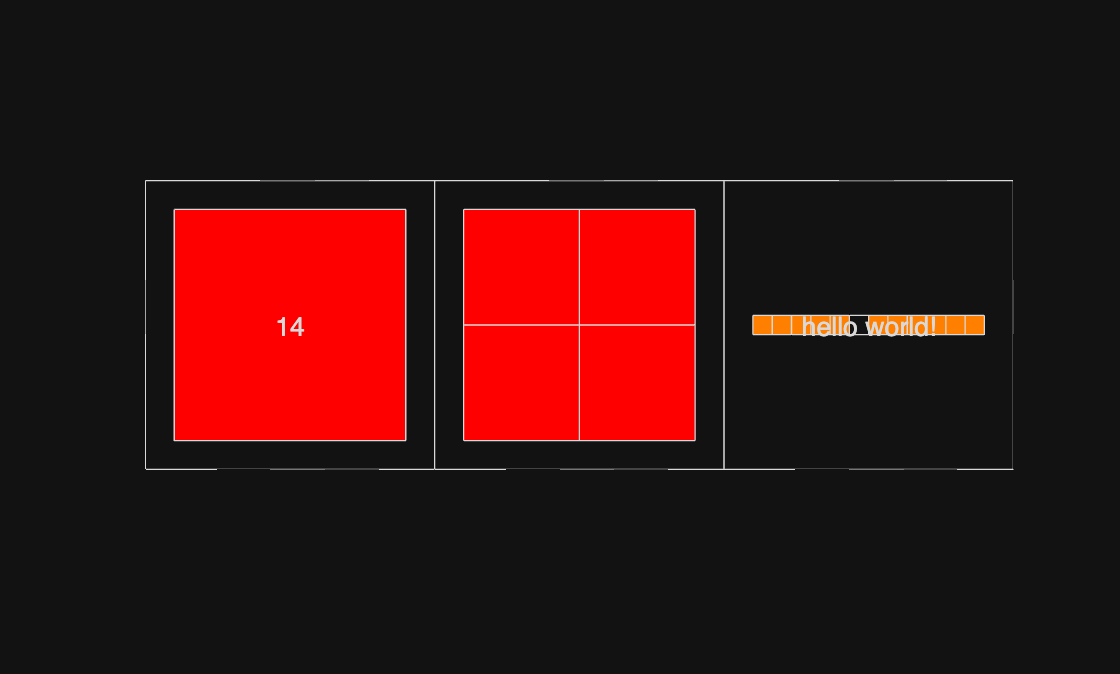

cellplot(c)

**Add data to cell array**

- Create/access entry with `{}`

- Assign contents of container with `= `

**Deleting data from cell array**

- Grab cell containers with `() `

- Delete containers by assigning the value `[]`

A = {}


A =

  0×0 empty cell array



A{1,1} = '() vs {}'

A = 1×1 cell array
    {'() vs {}'}


A{2,2} = 'is important'

A = 2×2 cell array
    {'() vs {}'}    {0×0 double    }
    {0×0 double}    {'is important'}


A{1,1} = [] %Doesn't delete cell entries

A = 2×2 cell array
    {0×0 double}    {0×0 double    }
    {0×0 double}    {'is important'}


A(1,:) = [] % Deletes cell entries

A = 1×2 cell array
    {0×0 double}    {'is important'}


**Combine Cell Arrays **

A = {'cell combine','works just like'};
B = {'numeric array combine',0};
[A,B]

ans = 1×4 cell array
    {'cell combine'}    {'works just like'}    {'numeric array combine'}    {[0]}


[A;B]

ans = 2×2 cell array
    {'cell combine'         }    {'works just like'}
    {'numeric array combine'}    {[              0]}


### Comma-Separated List

- List of MATLAB objects separated by commas 

- Each item displayed individually when printed 

- Useful in passing arguments to functions and assigning output variables 

- Can be generated using `{:}` operator in cell array 

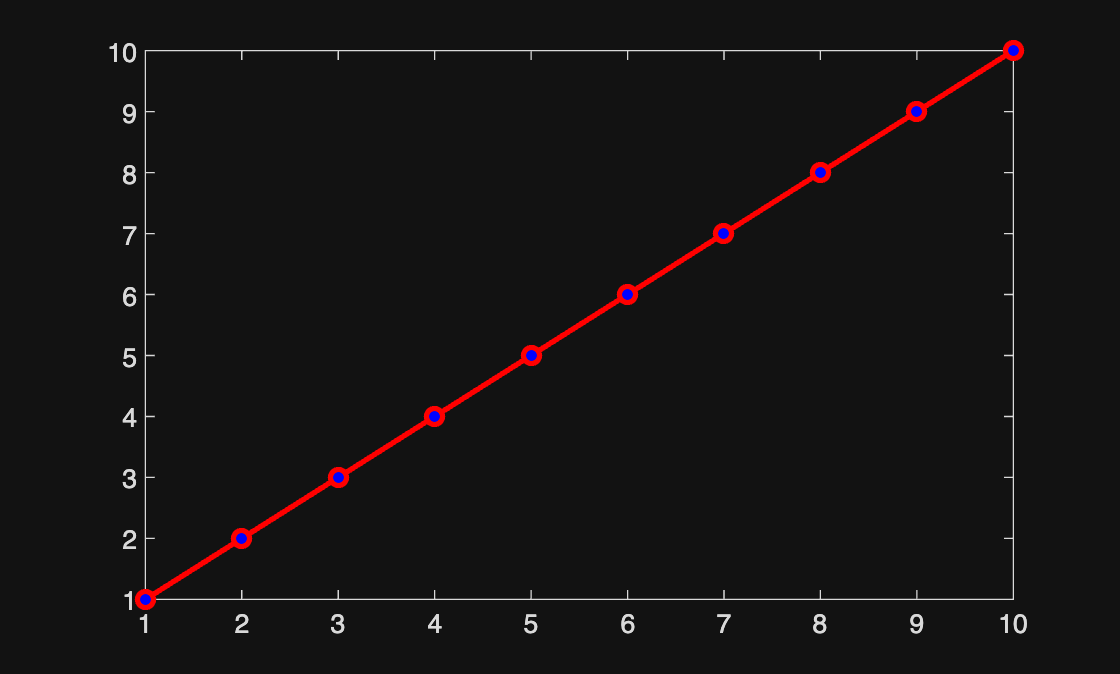

pstr={'ro-','linewidth',2,'markerfacecolor','b'};
plot(1:10,pstr{:}) % Pass comma−sep list to func

A={[1,2;5,4],[0,3,6;1,2,6]};
[A{:}]  

ans =      1     2     0     3     6
     5     4     1     2     6


### Memory Requirements

Cell arrays require additional memory to store information describing each cell

- Information is stored in a header 

- Memory required for header of single cell

a = 'a'; whos('a')

  Name      Size            Bytes  Class    Attributes

  a         1x1                 2  char               



b = 1; whos('b')

  Name      Size            Bytes  Class     Attributes

  b         1x1                 8  double              



c = {'a',1}; s = whos('c') 

s = struct with fields:
          name: 'c'
          size: [1 2]
         bytes: 250
         class: 'cell'
        global: 0
        sparse: 0
       complex: 0
       nesting: [1×1 struct]
    persistent: 0


Memory required for cell array: *head size x number of cells + data *(112 bytes per non-empty cell)

Contents of a single cell are stored contiguously. 

Storage is not necessarily contiguous between cells in array.

### Cell Array Functions

- `cell2mat` Convert cell array to numeric array 

- `cell2struct` Convert cell array to structure array 

- `cellfun` Apply function to each cell in cell array 

- `cellstr` Create cell array of strings from character array 

- `iscell` Determine whether input is cell array 

- `iscellstr` Determine whether input is cell array of strings 

- `mat2cell` Convert array to cell array 

- `num2cell` Convert array to cell array 

- `struct2cell` Convert structure to cell array 

EX.

A = {1,2,3}

A = 1×3 cell array
    {[1]}    {[2]}    {[3]}


cell2mat(A)

ans = 1×3
     1     2     3


cellfun(@sqrt,A)

ans = 1×3
    1.0000    1.4142    1.7321


num2cell(cell2mat(A))

ans = 1×3 cell array
    {[1]}    {[2]}    {[3]}


## Struct and Struct Arrays

Like cell arrays, can hold *arbitrary* MATLAB data types 

Unlike cell arrays, each entry associated with a field 

- Field-Value relationship 

Structures can be arranged in N-D arrays: **structure arrays **

**Create structure arrays **

- `struct` 

- `<var-name>.<field-name> = <field-value>`

**Access data from structure array **

- `()` to access structure from array 

- `.` to access field

st.a = {21,22,23}

st = struct with fields:
    a: {[21]  [22]  [23]}


classes=struct('name',{'CME292','CME302','CME500'},...
'units',{1,3,1},'grade',{'P','C','P'})

classes = 1×3 struct array with fields:
    name
    units
    grade


classes(1)

ans = struct with fields:
     name: 'CME292'
    units: 1
    grade: 'P'


**Concatenation of structures to form structure arrays**

- `horzcat, [ · , · ] `

- `vertcat, [ · ; · ]`

**Nested structures **

Create and access nested structure array with multiple () and . syntax

groups(2).students(4).firstName='Robert';
groups(2).students(4).lastName='Smith'

groups = 1×2 struct array with fields:
    students


groups(2).students

ans = 1×4 struct array with fields:
    firstName
    lastName


groups(2).students(4)

ans = struct with fields:
    firstName: 'Robert'
     lastName: 'Smith'


**Dynamic Field Names**

s = struct();
for i=1:3, s.(['P',num2str(i)]) = i; end
s

s = struct with fields:
    P1: 1
    P2: 2
    P3: 3


### Memory Requirements

Structs require additional memory to store information

- Information is stored in a *header* 

- Header for entire structure array

Each field of a structure requires contiguous memory.

Storage is not necessarily contiguous between fields in structure or structures in array. 

Structure of arrays is faster/cheaper than array of structures.

- Contiguous memory, Memory overhead 

### Structure Functions

- `fieldnames` Field names of structure 

- `getfield` Field of structure array 

- `isfield` Determine whether input is structure field 

- `isstruct` Determine whether input is structure array 

- `orderfields` Order fields of structure array 

- `rmfield` Remove fields from structure 

- `setfield` Assign values to structure array field 

- `arrayfun` Apply function to each element of array 

- `structfun` Apply function to each field of scalar structure

# Tables

## Categorical arrays

Categorical variables are values from a finite set of discrete categories.

state = {'MA','ME','CT','VT','ME','NH','VT','MA','NH','CT','RI'}; 
state = categorical(state)

state = 1×11 categorical array
     MA      ME      CT      VT      ME      NH      VT      MA      NH      CT      RI 


Categories of categorical array

categories(state)

ans = 6×1 cell array
    {'CT'}
    {'MA'}
    {'ME'}
    {'NH'}
    {'RI'}
    {'VT'}


Count occurrences of categorical array elements by category

countcats(state)

ans = 1×6
     2     2     2     2     1     2


Group data into bins or categories

A = rand(10,1)

A = 10×1
    0.0015
    0.8838
    0.4044
    0.3012
    0.9506
    0.4606
    0.2876
    0.0846
    0.5822
    0.1531


discretize(A,linspace(0,1,5))

ans = 10×1
     1
     4
     2
     2
     4
     2
     2
     1
     3
     1


## Tables

Many data structures naturally have a tabular form.

Data entries can be organized as rows, each row containing the same number of fields.

MATLAB introduced tables in R2013b.

### Functions

- `head/tail` Get top/bottom rows of table 

- `summary` Print summary of table 

- `groupsummary` Group summary computations 

- `istable` Determine whether input is table 

- `(inner/outer)join` Combine two tables by rows using key variables 

- `readtable/writetable` Read/write table from/to file 

- `ismissing` Find missing values 

- `varfun` Apply function to table variables 

- `rowfun` Apply function to table rows 

- `splitapply` Split data into groups and apply function 

- `stackedplot` Stacked plot of several variables with common x-axis

T = table([1:3]',{'one';'two';'three'},categorical({'A';'B';'C'}),...
    'VariableNames',["num","text","cat"]) 

T = 3×3 table
    num      text       cat
    ___    _________    ___

     1     {'one'  }     A 
     2     {'two'  }     B 
     3     {'three'}     C 


T.Properties

ans =   TableProperties with properties:

             Description: ''
                UserData: []
          DimensionNames: {'Row'  'Variables'}
           VariableNames: {'num'  'text'  'cat'}
           VariableTypes: ["double"    "cell"    "categorical"]
    VariableDescriptions: {}
           VariableUnits: {}
      VariableContinuity: []
                RowNames: {}
        CustomProperties: No custom properties are set.
      Use addprop and rmprop to modify CustomProperties.


T.Properties.RowNames = T.text;
T

T = 3×3 table
             num      text       cat
             ___    _________    ___

    one       1     {'one'  }     A 
    two       2     {'two'  }     B 
    three     3     {'three'}     C 


T2 = table({'one';'two'},{'Monday';'Tuesday'},...
         'VariableNames',["text","day"])

T2 = 2×2 table
     text          day    
    _______    ___________

    {'one'}    {'Monday' }
    {'two'}    {'Tuesday'}


T = join(T2,T,'Keys','text')

T = 2×4 table
     text          day        num    cat
    _______    ___________    ___    ___

    {'one'}    {'Monday' }     1      A 
    {'two'}    {'Tuesday'}     2      B 


### Timetables

- A special kind of table especially useful in scientific computing. 

- A specific time is associated with each row. Time is usually represented using `datetime` format (proleptic ISO calendar) 

- One can use all of table’s functions, as well as timetable specific functions.

#### Timetable Functions

- `timerange` Time range for timetable row subscripting 

- `retime` Resample or aggregate data in timetable 

- `synchronize` Synchronize timetables to common time vector 

- `istimetable` Determine whether input is timetable 

- `lag` Time-shift data in timetable 

- `withtol` Time tolerance for timetable row subscripting 

### Timetable Example

Importing Data

If you have regularly formatted tabular data in a single spreadsheet or a delimited text file, you can use the `readtable` function to import it into MATLAB.

hurrs = readtable("hurricaneData.txt")

hurrs = 200×5 table
    Number         Timestamp               Country         Windspeed    Pressure
    ______    ____________________    _________________    _________    ________

      1       18-Jun-1993 00:00:00    {'N/A'          }       29          1006  
      1       18-Jun-1993 06:00:00    {'N/A'          }       29          1005  
      1       18-Jun-1993 12:00:00    {'N/A'          }       29          1005  
      1       18-Jun-1993 18:00:00    {'N/A'          }       35          1005  
      1       19-Jun-1993 00:00:00    {'N/A'          }       35          1006  
      1       19-Jun-1993 06:00:00    {'N/A'          }       35          1006  
      1       19-Jun-1993 12:00:00    {'N/A'          }       40          1000  
      1       19-Jun-1993 18:00:00    {'N/A'          }       40          1000  

View properties of table

hurrs.Properties

ans =   TableProperties with properties:

             Description: ''
                UserData: []
          DimensionNames: {'Row'  'Variables'}
           VariableNames: {'Number'  'Timestamp'  'Country'  'Windspeed'  'Pressure'}
           VariableTypes: ["double"    "datetime"    "cell"    "double"    "double"]
    VariableDescriptions: {}
           VariableUnits: {}
      VariableContinuity: []
                RowNames: {}
        CustomProperties: No custom properties are set.
      Use addprop and rmprop to modify CustomProperties.


Remove *Country* column

hurrs.Country = []

hurrs = 200×4 table
    Number         Timestamp          Windspeed    Pressure
    ______    ____________________    _________    ________

      1       18-Jun-1993 00:00:00       29          1006  
      1       18-Jun-1993 06:00:00       29          1005  
      1       18-Jun-1993 12:00:00       29          1005  
      1       18-Jun-1993 18:00:00       35          1005  
      1       19-Jun-1993 00:00:00       35          1006  
      1       19-Jun-1993 06:00:00       35          1006  
      1       19-Jun-1993 12:00:00       40          1000  
      1       19-Jun-1993 18:00:00       40          1000  
      1       20-Jun-1993 00:00:00       40          1000  
      1       20-Jun-1993 06:00:00       40          1001  
      1       20-Jun-1993 12:00:00       35          1002  
      1       20-Jun-1993 18:00:00       35          1003  
   

Convert table to timetable, specify the second variable with dates and times, `Timestamp`, as the time vector of the timetable.

TT = table2timetable(hurrs,'RowTimes','Timestamp')

TT = 200×3 timetable
         Timestamp          Number    Windspeed    Pressure
    ____________________    ______    _________    ________

    18-Jun-1993 00:00:00      1          29          1006  
    18-Jun-1993 06:00:00      1          29          1005  
    18-Jun-1993 12:00:00      1          29          1005  
    18-Jun-1993 18:00:00      1          35          1005  
    19-Jun-1993 00:00:00      1          35          1006  
    19-Jun-1993 06:00:00      1          35          1006  
    19-Jun-1993 12:00:00      1          40          1000  
    19-Jun-1993 18:00:00      1          40          1000  
    20-Jun-1993 00:00:00      1          40          1000  
    20-Jun-1993 06:00

istimetable(TT)

ans = logical
   1


summary(TT)


TT: 200×3 timetable

Row Times:

    Timestamp: datetime

Variables:

    Number: double
    Windspeed: double
    Pressure: double

Statistics for applicable variables and row times:

                 NumMissing              Min                        Median                       Max                         Mean                   Std     

    Timestamp        0           18-Jun-1993 00:00:00        28-Aug-1993 21:00:00        21-Sep-1993 18:00:00        26-Aug-1993 02:43:48        553:47:47  
    Number           0                              1                           5                           8                      4.6700           1.9851  
    Windspeed        0                             23                          46                       

Specify a time range in August 1993

start_time = datetime('8/1/1993 00:00:00','InputFormat',"MM/dd/uuuu HH:mm:ss")

start_time = datetime
   01-Aug-1993


end_time = datetime('10-Aug-1993 00:00:00','InputFormat',"dd-MMM-uuuu HH:mm:ss")

end_time = datetime
   10-Aug-1993


S = timerange(start_time,end_time,"openright")

S = 	timetable timerange subscript:

		Select timetable rows with times in the half-open interval:
		  Starting at, including:   01-Aug-1993 00:00:00
		  Ending at, but excluding: 10-Aug-1993 00:00:00

	See Select Times in Timetable.


Select rows with times in the range specified by `S`.

TT2 = TT(S,:)

TT2 = 22×3 timetable
         Timestamp          Number    Windspeed    Pressure
    ____________________    ______    _________    ________

    04-Aug-1993 12:00:00      2          35          1010  
    04-Aug-1993 18:00:00      2          35          1009  
    05-Aug-1993 00:00:00      2          40          1008  
    05-Aug-1993 06:00:00      2          46          1007  
    05-Aug-1993 12:00:00      2          52          1006  
    05-Aug-1993 18:00:00      2          52          1006  
    06-Aug-1993 00:00:00      2          52          1006  
    06-Aug-1993 06:00:00      2          58          1005  
    06-Aug-1993 12:00:00      2          58          1005  
    06-Aug-1993 18:00

Check if times are **regular**. The input is regular if its times are in a sequence that is strictly monotone (either increasing or decreasing) with a unique time step.

diff(TT2.Timestamp)

ans = 21×1 duration array
   06:00:00
   06:00:00
   06:00:00
   06:00:00
   06:00:00
   06:00:00
   06:00:00
   06:00:00
   06:00:00
   06:00:00
   06:00:00
   06:00:00
   06:00:00
   06:00:00
   06:00:00
   06:00:00
   06:00:00
   06:00:00
   06:00:00
   06:00:00
   06:00:00


isregular(TT2)

ans = logical
   1


Shift the data forward in time by one time step and compare it to the original timetable.

TT3 = lag(TT2)

TT3 = 22×3 timetable
         Timestamp          Number    Windspeed    Pressure
    ____________________    ______    _________    ________

    04-Aug-1993 12:00:00     NaN         NaN          NaN  
    04-Aug-1993 18:00:00       2          35         1010  
    05-Aug-1993 00:00:00       2          35         1009  
    05-Aug-1993 06:00:00       2          40         1008  
    05-Aug-1993 12:00:00       2          46         1007  
    05-Aug-1993 18:00:00       2          52         1006  
    06-Aug-1993 00:00:00       2          52         1006  
    06-Aug-1993 06:00:00       2          52         1006  
    06-Aug-1993 12:00:00       2          58         1005  
    06-Aug-1993 18:00

Synchronize the two timetables for comparison.

synchronize(TT2,TT3)

ans = 22×6 timetable
         Timestamp          Number_TT2    Windspeed_TT2    Pressure_TT2    Number_TT3    Windspeed_TT3    Pressure_TT3
    ____________________    __________    _____________    ____________    __________    _____________    ____________

    04-Aug-1993 12:00:00        2              35              1010           NaN             NaN              NaN    
    04-Aug-1993 18:00:00        2              35              1009             2              35             1010    
    05-Aug-1993 00:00:00        2              40              1008             2              35             1009    
    05-Aug-1993 06:00:00        2              46              1007          

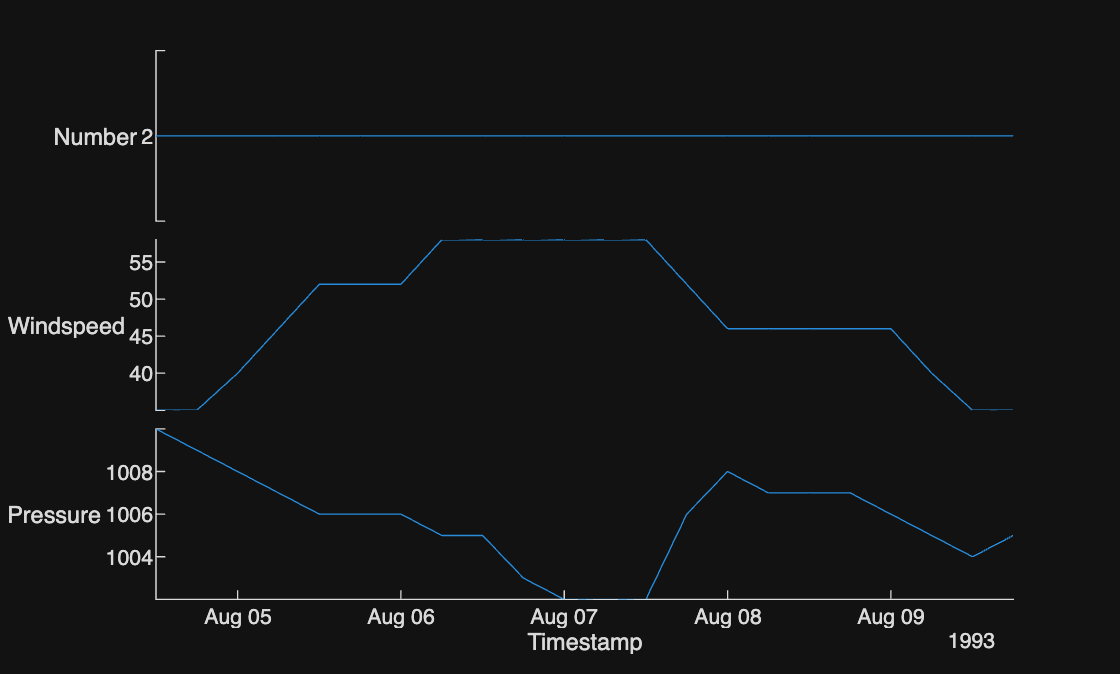

stackedplot(TT2);

#### *More on data visualization later...*

#### Quiz.

Compute the mean windspeed on August 5th 1993 from the data. 

**The files has been posted to Canvas. *

**Hint: use *`varfun`* or *`retime`

# Function and Function Handle

### Scripts vs. Functions

**Scripts **

- Execute a series of MATLAB statements 

- Uses base workspace (does not have own workspace) 

- Parsed and loaded into memory every execution 

**Functions** 

- Accept inputs, execute a series of MATLAB statements, and return outputs 

- Local workspace defined only during execution of function: `global, persistent` variables and `evalin, assignin` commands help share variables between workspaces or allow them to persist between function executions. More info at [https://www.mathworks.com/help/matlab/matlab_prog/share-data-between-workspaces.html](https://www.mathworks.com/help/matlab/matlab_prog/share-data-between-workspaces.html). 

- Local, nested, private, anonymous, class methods 

- Parsed and loaded into memory during first execution

### Anonymous Functions

Functions not stored in a program file, but associated with a variable

- Stored directly in function handle 

- Store expression and require variables 

- Zero or more arguments allowed 

- Nested anonymous functions permitted 

- Only a single executable statement

f1 = @(x,y) [sin(pi*x), cos(pi*y), tan(pi*x*y)];
f1(0.5,0.25)

ans = 1×3
    1.0000    0.7071    0.4142


Array of function handle not allowed; function handle may return array

integral(@(x) exp(1)*x.^2,-1,1)

ans = 1.8122

### Local Functions

A given MATLAB file can contain multiple functions 

The first function is the **main** function 

- Callable from anywhere, provided it is in the search path 

Other functions in file are local functions 

- Only callable from main function or other local functions in same file 

- Enables modularity (large number of small functions) without creating a large number of files 

- Unfavorable from code reusability standpoint

### Nested Functions 

A nested function is a function completely contained within some parent function. 

Useful as an alternative to anonymous function that can’t be confined to a single line 

Can’t be defined within MATLAB control statements `if/elseif/else, switch/case, for, while, `or` try/catch `

Variables sharable between parent and nested functions 

If variable in nested function is not used in parent function, it remains local to the nested function 

Multiple levels of nesting is permitted. Nested function available from:

- Level immediately above 

- Function nested at same level with same parent 

- Function at any lower level 

Ex. n`ested_ex.m`

### Private Functions 

Private functions are useful for limiting the scope of a function 

Designate a function as private by storing it in a subfolder named private 

Only available to functions/scripts in the folder immediately above the private subfolder

### Evaluate/Assign in Another Workspace

Evaluate expression in other workspace ('`caller`', '`base`') 

- `evalin(ws,expression) `

- Useful for evaluating expression in caller’s workspace without passing name variables as function arguments

a = evalin('base','2+3')

a = 5

Assign variable in other workspace ('`caller`', '`base`') 

- `assignin(ws, 'var', val) `

- Useful for circumventing local scope restrictions of functions

assignin('base','b','hello')
b

b = 'hello'

### Variable Number of Inputs/Outputs

Query number of inputs passed to a function 

- `nargin` 

- Don’t try to pass more than in function declaration 

Determine number of outputs requested from function 

- `nargout` 

- Don’t request more than in function declaration

nargin(@cat)

ans = -1

Input-output argument list length unknown or conditional 

- Think of plot, get, set and the various Name-Property pairs that can be specified in a given function call 

Use `varargin` as last function input and `varargout` as last function output for input/output argument lists to be of variable length

All arguments prior to `varargin/varargout` will be matched one-to-one with calling expression 

Remaining input/outputs will be stored in a cell array named `varargin/varargout`

Ex.` vararg_ex.m`

[b,vo1,vo2,vo3,vo4] = vararg_ex(2,'variable','input/output','example','!')

b = 4

vo1 = 'variable'

vo2 = 'input/output'

vo3 = 'example'

vo4 = '!'

[b,~] = vararg_ex(3,'variable','input/output')

b = 9

## Function Handle (`@`)

Callable association to MATLAB function stored in variable 

- Enables invocation of function outside its normal scope 

- Invoke function indirectly 

- Variable

Capture data for later use

Enables passing functions as arguments 

- Optimization 

- Solution of nonlinear systems of equations 

- Solution of ODEs 

- Numerical Integration

Function handles must be scalars, i.e. can’t be indexed with` ()`

Example at the end of the live script file.

#### Example of function handle: Trapezoidal rule for integration


$$\int_a^b f\left(x\right)\textrm{dx}\approx \sum_{i=1}^n \frac{b-a}{2n}\left\lbrack f\left(x_{i-\frac{1}{2}} \right)+\left(x_{i+\frac{1}{2}} \right)\right\rbrack$$
 

a = exp(1);
f = @(x) a*x.^2;
trap_rule(f,-1,1,1000) 

ans = 1.8122

**Trapezoidal rule for integration function**

You may also create a function file `trap_rule.m` first, using the code in this section.

function int_f = trap_rule(f,a,b,n)
    x=linspace(a,b,n+1)';
    int_f=0.5*((b-a)/n)*sum(f(x(1:end-1))+f(x(2:end)));
end